cd 'C:\Users\elite\OneDrive\Desktop\School\HRI\MiniVIE'
MiniVIE.configurePath

[MiniVIE.m] Configured MiniVIE path at: C:\Users\elite\OneDrive\Desktop\School\HRI\MiniVIE



hMyo = Inputs.MyoUdp.getInstance();

[MyoUdp] Returning existing object


hMyo.initialize();

[UserConfig.m] myoUdpRate=200
[MyoUdp] UDP Comms already initialized


[MiniVIE.m] Configured MiniVIE path at: C:\Users\elite\OneDrive\Desktop\School\HRI\MiniVIE
[UserConfig.m] userFilePrefix=USER_


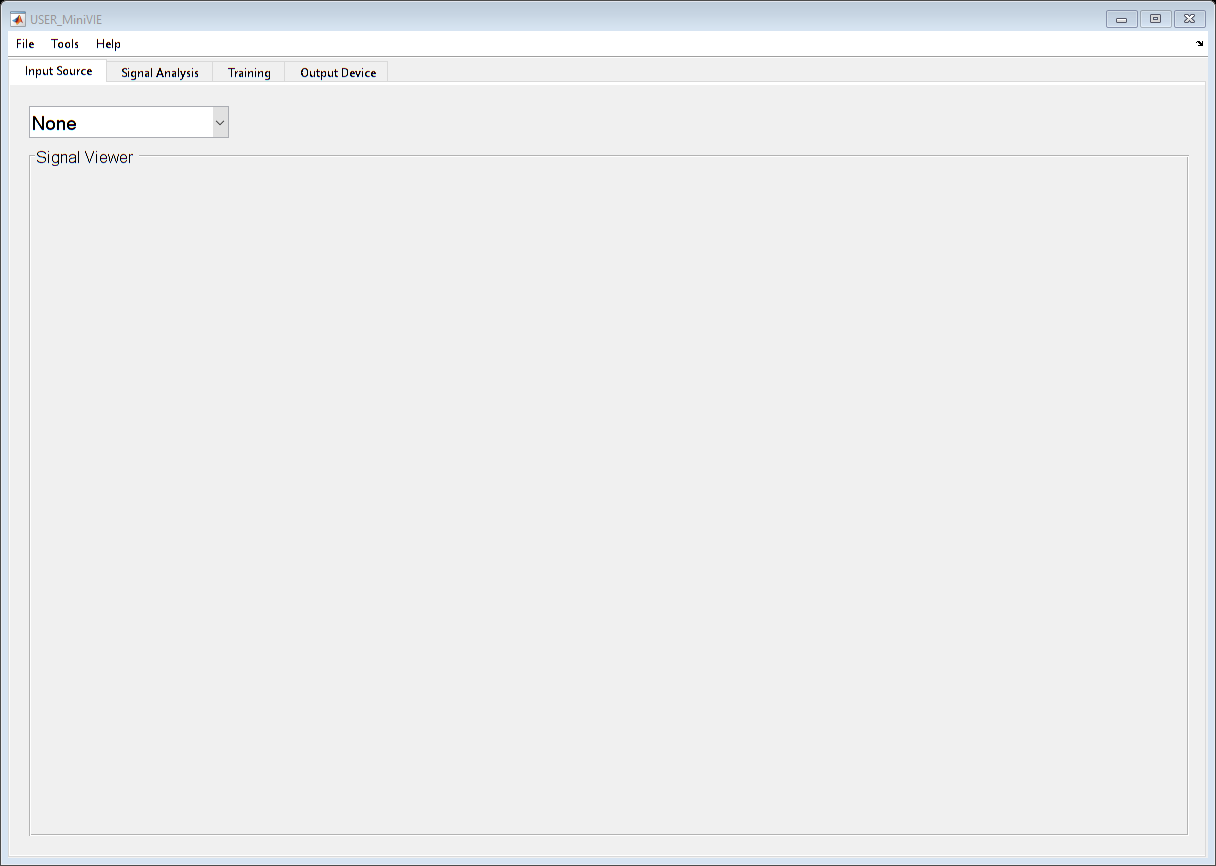

obj = MiniVIE;

% matlab.engine.shareEngine;
% matlab.engine.engineName
% 
% sprintf('Please connect to the engine using the python script')
% pause();

% CHANGE THIS TO MATCH YOUR TRAINING DATA FILE
myDataFilename = '../../train.trainingData';
 
% Load training data file
hData = PatternRecognition.TrainingData();

[TrainingData] Creating Empty Training Data Object


hData.loadTrainingData(myDataFilename);

[TrainingData] Loading file: "../../train.trainingData"
[TrainingData] Loading 2559 Samples
[TrainingData] Setting window size to 250.
[TrainingData] Sample rate empty.  Assuming 1000Hz


 
% Create EMG Myo Interface Object
hMyo = Inputs.MyoUdp.getInstance();

[MyoUdp] Returning existing object


hMyo.initialize();

[UserConfig.m] myoUdpRate=200
[MyoUdp] UDP Comms already initialized


 
% Create LDA Classifier Object
hLda = SignalAnalysis.Lda;
hLda.initialize(hData);

[UserConfig.m] FeatureExtract.zcThreshold=0.05
[UserConfig.m] FeatureExtract.sscThreshold=0.05


hLda.train();

Training LDA with 1225 Samples (1 = 206; 2 = 206; 3 = 204; 4 = 0; 5 = 200; 6 = 206; 7 = 203; )
Active Channels are: [ 1 2 3 4 5 6 7 8 ]
[Lda] Classes with no data [ 4 ] 


hLda.computeError();

Percent correctly classified:  100.0 %  (1225 samples)
         Power Grasp Class accuracy:	  100.0 % 	( 206 of  206)
    Wrist Extend Out Class accuracy:	  100.0 % 	( 206 of  206)
       Wrist Flex In Class accuracy:	  100.0 % 	( 204 of  204)
           Hand Open Class accuracy:	    0.0 % 	(   0 of    0)
     Wrist Abduction Class accuracy:	  100.0 % 	( 200 of  200)
     Wrist Adduction Class accuracy:	  100.0 % 	( 206 of  206)
         No Movement Class accuracy:	  100.0 % 	( 203 of  203)


 
StartStopForm([]); % initialize a small gui utility to control a while loop

% MATLAB script to send data to Python server
% Establish connection to the Python server
host = 'localhost';
port = 65432;
client = tcpclient(host, port);

while StartStopForm
        
    % Get the appropriate number of EMG samples for the 8 myo channels
    emgData = hMyo.getData(hLda.NumSamplesPerWindow,1:8);
    
    % Extract features and classify
    features2D = hLda.extractfeatures(emgData);
    [classDecision, voteDecision] = hLda.classify(reshape(features2D',[],1));
    
    % Display the resulting class number and name
    classNames = hLda.getClassNames;
    className = classNames{classDecision};
    fprintf('Class=%2d; Class = %16s;\n',classDecision,className);
    
    % refresh the display
    drawnow;

    send_data_to_server(client, className + ",")

    pause(2)
end

Class= 7; Class =      No Movement;
Class= 6; Class =  Wrist Adduction;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 5; Class =  Wrist Abduction;
Class= 7; Class =      No Movement;
Class= 5; Class =  Wrist Abduction;
Class= 6; Class =  Wrist Adduction;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Movement;
Class= 7; Class =      No Mo


%clear client

% Function to send data to the Python server

function send_data_to_server(client, value)
    write(client, num2str(value), 'string');
end
